% Exemple de paramètres DH
theta = [0, pi/2, 0];   % Angles de rotation autour de l'axe z
d = [2, 0, 0];          % Distance le long de l'axe z
a = [0, 3, 2];          % Distance le long de l'axe x
alpha = [pi/2, 0, pi/2];% Angles de rotation autour de l'axe x

% Initialiser la transformation homogène
T = eye(4);

% Initialiser les tableaux pour stocker les coordonnées des articulations
x_coords = zeros(numel(theta) + 1, 1)

x_coords =      0
     0
     0
     0


y_coords = zeros(numel(theta) + 1, 1)

y_coords =      0
     0
     0
     0


z_coords = zeros(numel(theta) + 1, 1)

z_coords =      0
     0
     0
     0



% Boucle sur les joints
for i = 1:numel(theta)
    % Calculer la transformation entre les repères adjacents
    Ti = [
        cos(theta(i)), -sin(theta(i))*cos(alpha(i)), sin(theta(i))*sin(alpha(i)), a(i)*cos(theta(i));
        sin(theta(i)), cos(theta(i))*cos(alpha(i)), -cos(theta(i))*sin(alpha(i)), a(i)*sin(theta(i));
        0, sin(alpha(i)), cos(alpha(i)), d(i);
        0, 0, 0, 1
    ];
    % Afficher la transformation pour cette articulation
    fprintf('Transformation pour l''articulation %d :\n', i);
    disp(Ti);

    % Multiplier les transformations
    T = T * Ti

    % Extraire les coordonnées de la position de l'articulation actuelle
    % (matrice de position) j'extraie les coordonnées x, y et z de la position de l'articulation actuelle à partir de la matrice de transformation homogène T
    x_coords(i+1) = T(1, 4)
    y_coords(i+1) = T(2, 4)
    z_coords(i+1) = T(3, 4)
end

Transformation pour l'articulation 1 :


    1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    2.0000
         0         0         0    1.0000



T =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    2.0000
         0         0         0    1.0000


x_coords =      0
     0
     0
     0


y_coords =      0
     0
     0
     0


z_coords =      0
     2
     0
     0


Transformation pour l'articulation 2 :


    0.0000   -1.0000         0    0.0000
    1.0000    0.0000         0    3.0000
         0         0    1.0000         0
         0         0         0    1.0000



T =     0.0000   -1.0000         0    0.0000
    0.0000    0.0000   -1.0000    0.0000
    1.0000    0.0000    0.0000    5.0000
         0         0         0    1.0000


x_coords = 1.0e-15 *

         0
         0
    0.1837
         0


y_coords = 1.0e-15 *

         0
         0
    0.1837
         0


z_coords =      0
     2
     5
     0


Transformation pour l'articulation 3 :


    1.0000         0         0    2.0000
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000



T =     0.0000   -0.0000    1.0000    0.0000
    0.0000   -1.0000   -0.0000    0.0000
    1.0000    0.0000   -0.0000    7.0000
         0         0         0    1.0000


x_coords = 1.0e-15 *

         0
         0
    0.1837
    0.3062


y_coords = 1.0e-15 *

         0
         0
    0.1837
    0.3062


z_coords =      0
     2
     5
     7


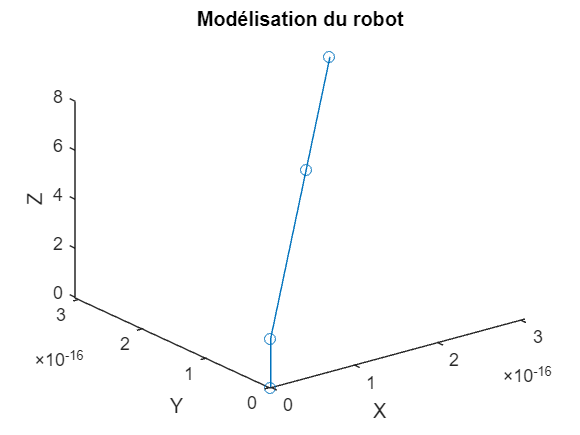


% Tracer les liens entre les articulations
plot3(x_coords, y_coords, z_coords, '-o');

% Configurer le graphique
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Modélisation du robot');